%Project 7 - Profit vs Production
%Benjamin Oakes - Engineering Computer Applications

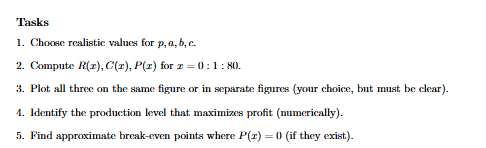

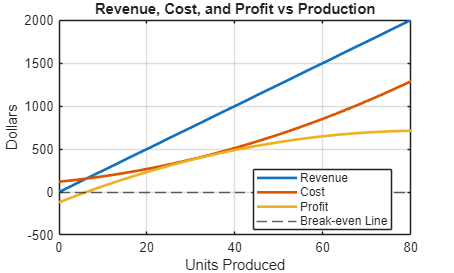



% Clears all variables from workspace
clear;

% Clears command window
clc;

% Closes all open figure windows
close all;



% Creates a vector of production values from 0 to 80
x = 0:1:80;

% Selling price per unit
p = 25;

% Quadratic cost coefficient
% Controls how quickly costs increase at high production
a = 0.12;

% Linear cost coefficient
% Represents variable production cost per unit
b = 5;

% Fixed startup cost
c = 120;


% Calculates revenue for every production level
% Revenue = price * number of units
R = p .* x;

% Calculates cost for every production level
% Cost = ax^2 + bx + c
C = a .* x.^2 + b .* x + c;

% Calculates profit
% Profit = Revenue - Cost
P = R - C;


% Finds the maximum value inside the profit vector
% maxProfit = highest profit value
% maxIndex = location of that value in the vector
[maxProfit, maxIndex] = max(P);

% Uses the index to determine production level
bestProduction = x(maxIndex);


% Finds where the profit changes sign
% A sign change means the graph crossed zero
breakEvenIndex = find(P(1:end-1) .* P(2:end) <= 0);

% Creates an empty array to store break-even values
breakEvenPoints = [];

% Loops through each sign change location
for i = breakEvenIndex
    
    % Gets first x-value
    x1 = x(i);
    
    % Gets second x-value
    x2 = x(i+1);
    
    % Gets first profit value
    y1 = P(i);
    
    % Gets second profit value
    y2 = P(i+1);
    
    % Uses linear interpolation to estimate
    % where profit equals zero
    xBreakEven = x1 - y1 * (x2 - x1) / (y2 - y1);
    
    % Adds estimated break-even point to array
    breakEvenPoints = [breakEvenPoints xBreakEven];
end

% Creates a new figure window
figure;

% Plots revenue curve
plot(x, R, 'LineWidth', 2);

% Keeps current graph so more lines can be added
hold on;

% Plots cost curve
plot(x, C, 'LineWidth', 2);

% Plots profit curve
plot(x, P, 'LineWidth', 2);

% Draws horizontal line at y = 0
% Helps visualize break-even points
yline(0, '--');

% Turns grid on
grid on;

% Adds graph title
title('Revenue, Cost, and Profit vs Production');

% Labels x-axis
xlabel('Units Produced');

% Labels y-axis
ylabel('Dollars');

% Adds legend to identify curves
legend('Revenue', 'Cost', 'Profit', ...
       'Break-even Line', ...
       'Location', 'best');

% Saves figure as PNG image
saveas(gcf, 'project6_revenue_cost_profit.png');

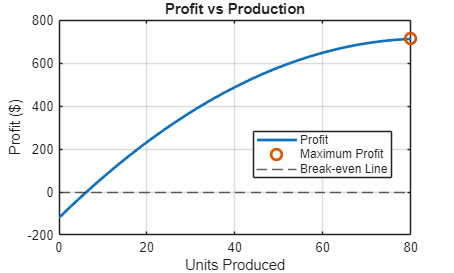


% Creates another figure window
figure;

% Plots profit curve
plot(x, P, 'LineWidth', 2);

% Keeps graph active
hold on;

% Plots maximum profit point
plot(bestProduction, maxProfit, ...
     'o', ...
     'MarkerSize', 8, ...
     'LineWidth', 2);

% Draws horizontal line at y = 0
yline(0, '--');

% Turns grid on
grid on;

% Adds graph title
title('Profit vs Production');

% Labels x-axis
xlabel('Units Produced');

% Labels y-axis
ylabel('Profit ($)');

% Adds legend
legend('Profit', ...
       'Maximum Profit', ...
       'Break-even Line', ...
       'Location', 'best');

% Saves second figure
saveas(gcf, 'project6_profit_only.png');


% Creates table containing all calculated values
resultsTable = table(x', R', C', P', ...
    'VariableNames', ...
    {'UnitsProduced', 'Revenue', 'Cost', 'Profit'});

% Displays table in command window
disp(resultsTable);

    UnitsProduced    Revenue     Cost     Profit 
    _____________    _______    ______    _______

          0              0         120       -120
          1             25      125.12    -100.12
          2             50      130.48     -80.48
          3             75      136.08     -61.08
          4            100      141.92     -41.92
          5            125         148        -23
          6            150      154.32      -4.32
          7            175      160.88      14.12
          8            200      167.68      32.32
          9            225      174.72      50.28
         10            250         182         68
         11            275      189.52      85.48
         12            300      197.28     102.72
         13            325      205.28     119.72
         14            350      213.52     136.48
         15  


% Displays production level with highest profit
fprintf('Maximum profit occurs at %d units.\n', ...
        bestProduction);

Maximum profit occurs at 80 units.



% Displays maximum profit amount
fprintf('Maximum profit is $%.2f.\n', ...
        maxProfit);

Maximum profit is $712.00.



% Checks if any break-even points exist
if isempty(breakEvenPoints)
    
    % Displays message if none exist
    fprintf('No break-even points found in the production range.\n');
    
else
    
    % Displays break-even header
    fprintf('Approximate break-even point(s):\n');
    
    % Displays break-even values
    disp(breakEvenPoints);
end

Approximate break-even point(s):


    6.2343

